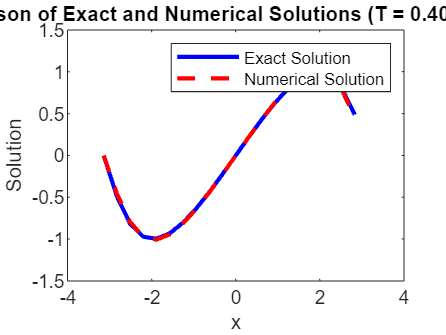

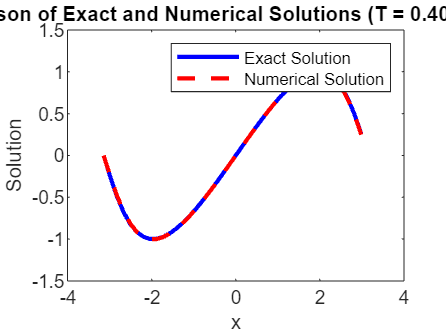

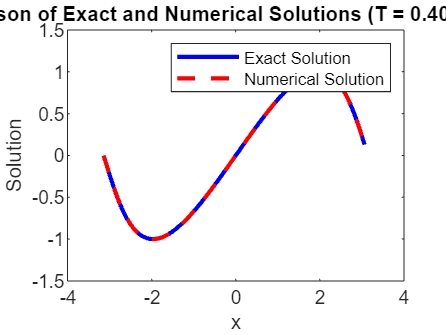

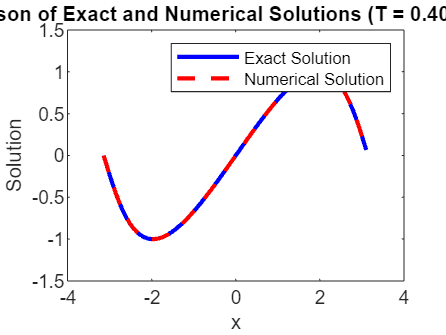

alpha = 0, T = 0.400000


   3.2842e-02            0
   1.0437e-02   1.6539e+00
   3.6632e-03   1.5105e+00
   1.4725e-03   1.3148e+00



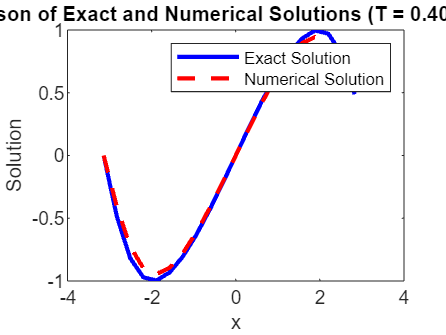

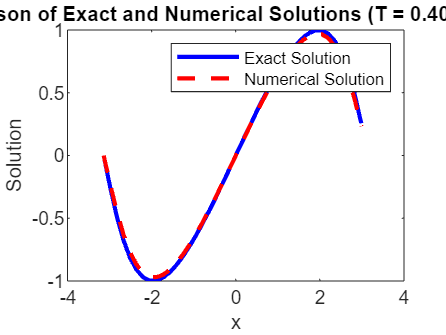

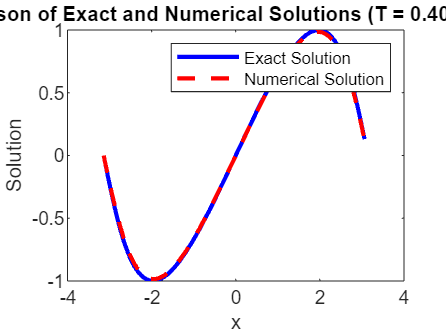

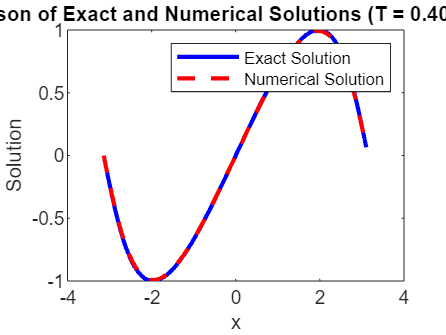

alpha = 1, T = 0.400000


   1.2650e-01            0
   6.3381e-02   9.9701e-01
   3.1591e-02   1.0045e+00
   1.5752e-02   1.0039e+00



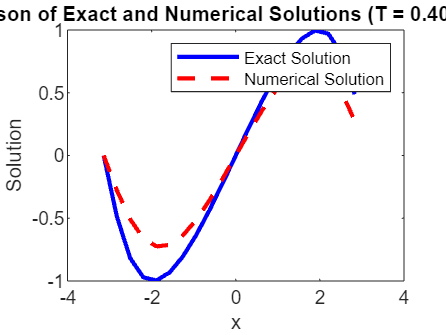

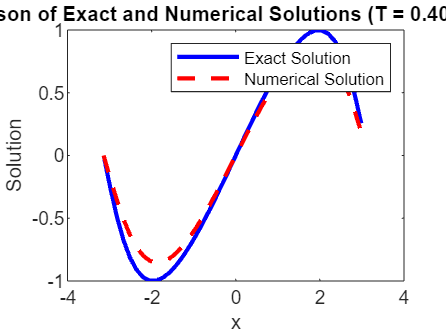

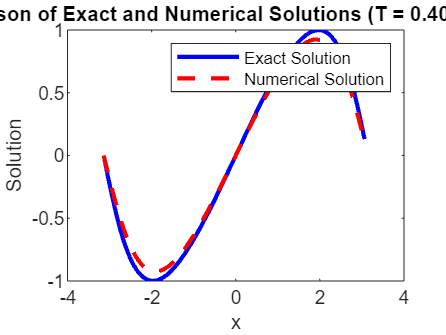

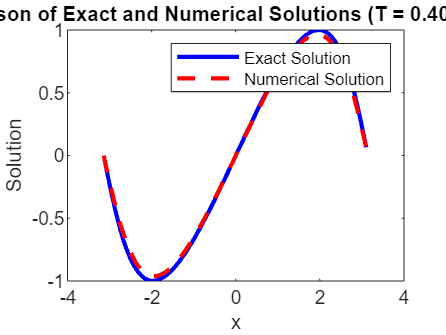

alpha = 5, T = 0.400000


   5.0657e-01            0
   2.7954e-01   8.5771e-01
   1.4801e-01   9.1737e-01
   7.6402e-02   9.5402e-01



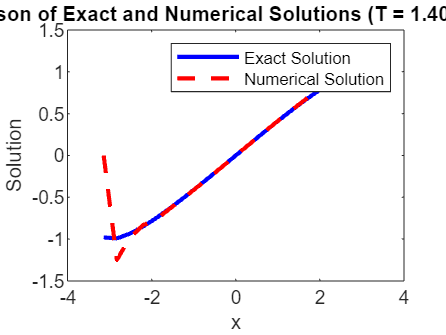

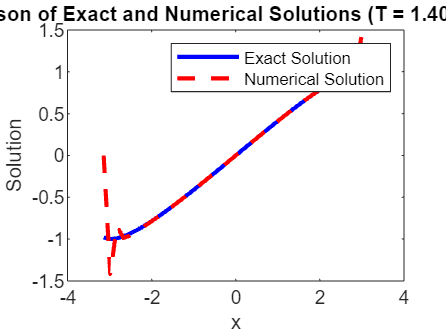

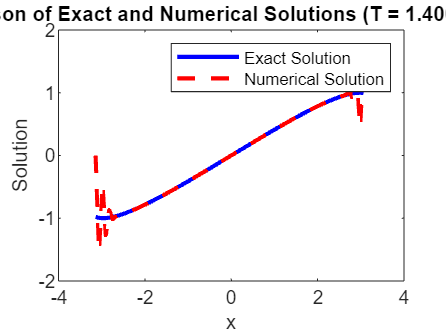

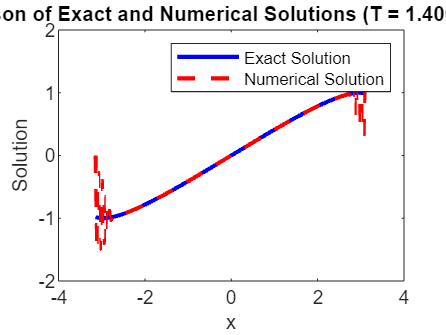

alpha = 0, T = 1.400000


   5.8734e-01            0
   4.6091e-01   3.4971e-01
   4.2609e-01   1.1334e-01
   4.1577e-01   3.5353e-02



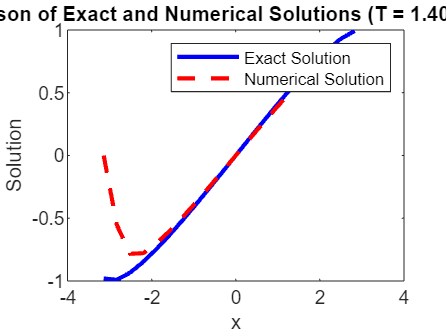

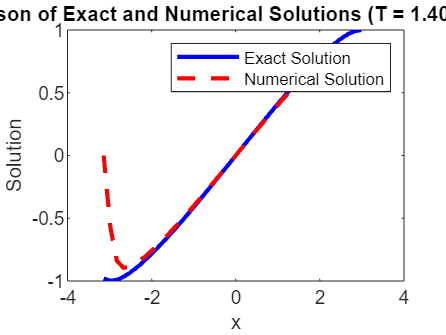

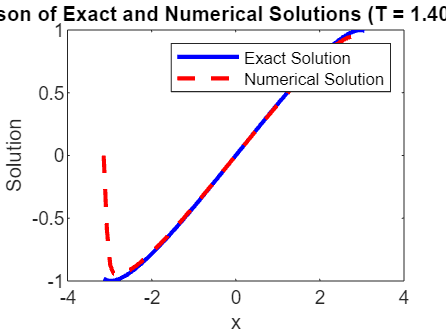

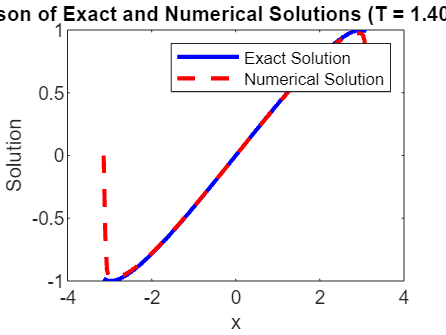

alpha = 1, T = 1.400000


   6.6452e-01            0
   4.6948e-01   5.0125e-01
   3.2292e-01   5.3988e-01
   2.1910e-01   5.5959e-01



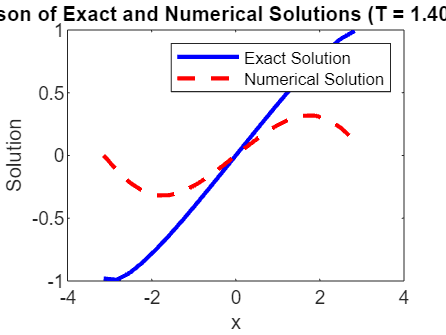

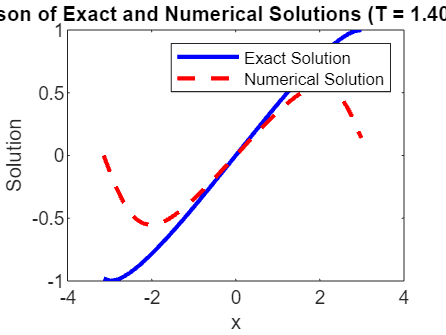

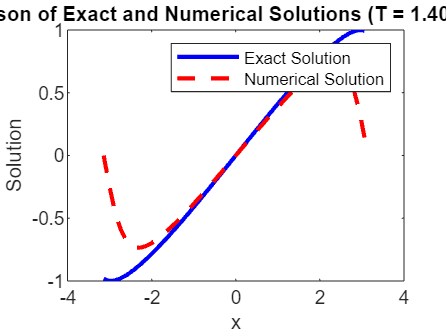

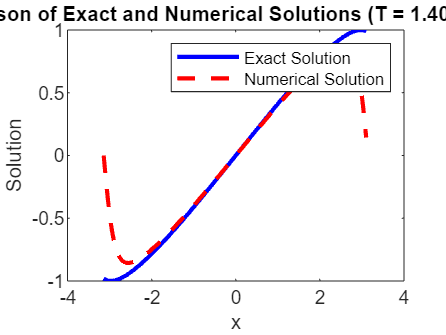

alpha = 5, T = 1.400000


   1.2395e+00            0
   9.2847e-01   4.1679e-01
   6.7258e-01   4.6514e-01
   4.7542e-01   5.0052e-01



% Sanaz Hami
% Rewriting Problem 3 of Homework 10

% Initialize parameters
xa = -pi;
xb = pi;
T_values = [0.4, 1.4]; % Final time values
a_values = [0, 1, 5]; 
lambda = 0.1;
v0 = @(x) sin(x); 
f = @(u) u.^2 / 2; 

for T_idx = 1:length(T_values)
    T = T_values(T_idx);
    for a_idx = 1:length(a_values)
        a = a_values(a_idx);
        errtab = zeros(4, 2); % Initialize error table

        % Loop over different mesh refinements
        for kk = 1:4
            Nx = 20 * (2^(kk - 1)) - 1; % Number of spatial points
            h = (xb - xa) / (Nx + 1); % Mesh size
            k = lambda * h; % Time step size
            x = linspace(xa, xb - h, Nx + 1); % Spatial grid

            % Initialize solution vector
            v = zeros(1, Nx + 3);
            v(2:Nx+2) = v0(x);
            v(1) = v(Nx+2);
            v(Nx+3) = v(2);

            % Time marching
            for ii = 1:floor(T / k)
                % Update solution
                v = update_solution(v, k, h, f, a, Nx);
            end

            % Final time step to reach exactly T
            k = T - floor(T / k) * k;
            v = update_solution(v, k, h, f, a, Nx);

            % Compute error
            u_exac = arrayfun(@(x) sin(burgers_sine(x, T)), x);
            errtab(kk, 1) = sqrt(sum((u_exac - v(2:Nx+2)).^2 * h));

            % Plotting the results
            figure;
            plot(x, u_exac, 'b-', 'LineWidth', 2);
            hold on;
            plot(x, v(2:Nx+2), 'r--', 'LineWidth', 2);
            title(sprintf('Comparison of Exact and Numerical Solutions (T = %f, a = %d)', T, a));
            xlabel('x');
            ylabel('Solution');
            legend('Exact Solution', 'Numerical Solution');
            hold off;
        end

        % Compute the order of accuracy
        for kk = 2:4
            errtab(kk, 2) = log(errtab(kk-1, 1) / errtab(kk, 1)) / log(2);
        end

        % Display results
        fprintf('alpha = %d, T = %f\n', a, T);
        disp(errtab);
    end
end


% Function to update solution

function v_new = update_solution(v, k, h, f, a, Nx)
    v_new = zeros(size(v));
    for jj = 2:Nx+2
        v_new(jj) = v(jj) - k / h * ((f(v(jj)) + f(v(jj+1))) / 2 - a * (v(jj+1) - v(jj)) / 2 - ((f(v(jj-1)) + f(v(jj))) / 2 - a * (v(jj) - v(jj-1)) / 2));
    end
    v_new(1) = v_new(Nx+2);
    v_new(Nx+3) = v_new(2);
end

